## *Jubair Bin Masud*

## *220021133*

## *Lab 8 Assignment*

## *05/08/25*

### **Exercise - 01**

amicable_pair(220,374) 

ans = logical
   0


amicable_pair(2620,2924) 

ans = logical
   1


amicable_pair(66928,66992) 

ans = logical
   1


**Exercise - 02**

goldbach_marginal(15)

ans =      2     2    11
     3     5     7
     5     5     5


goldbach_marginal(18)

ans =      2     3    13
     2     5    11


goldbach_marginal(5)

Error using eee_4416_ass_8>goldbach_marginal
Numbers below or equal to 5 don't satisfy the conjecture.

**Exercise - 03**

lunar_add(5,9)

ans = 9

lunar_add(482,24314)

ans = 24484

lunar_add(169,248,'Addition')

ans = 269

lunar_add(482,24314,'Multiplication')

unsloved


ans = 0

**Exercise - 04**

Departments = ["CSE"; "EEE"; "ME"; "CIVIL"; "CE"; "Architecture"; "Management"];
BUET = [120; 180; 150; 195; 40; 100; 50];
RUET = [120; 120; 80; 80; NaN; 50; 50];
KUET = [100; 150; 150; 150; 30; 80; NaN];
CUET = [80; 80; 80; 80; 80; 80; 80];
IUT = [40; 80; 55; 45; NaN; NaN; 30];


University_BD = table(BUET,RUET,KUET,CUET,IUT, RowNames = Departments)

University_BD = 7×5 table
                    BUET    RUET    KUET    CUET    IUT
                    ____    ____    ____    ____    ___

    CSE             120     120     100      80      40
    EEE             180     120     150      80      80
    ME              150      80     150      80      55
    CIVIL           195      80     150      80      45
    CE               40     NaN      30      80     NaN
    Architecture    100      50      80      80     NaN
    Management       50      50     NaN      80      30



sum(University_BD.CUET,'omitnan')

ans = 560


University_BD.DU = [100; 90; 85; 95; 70; 60; 65]

University_BD = 7×6 table
                    BUET    RUET    KUET    CUET    IUT    DU 
                    ____    ____    ____    ____    ___    ___

    CSE             120     120     100      80      40    100
    EEE             180     120     150      80      80     90
    ME              150      80     150      80      55     85
    CIVIL           195      80     150      80      45     95
    CE               40     NaN      30      80     NaN     70
    Architecture    100      50      80      80     NaN     60
    Management       50      50     NaN      80      30     65



University_BD("Management", :) = []

University_BD = 6×6 table
                    BUET    RUET    KUET    CUET    IUT    DU 
                    ____    ____    ____    ____    ___    ___

    CSE             120     120     100      80      40    100
    EEE             180     120     150      80      80     90
    ME              150      80     150      80      55     85
    CIVIL           195      80     150      80      45     95
    CE               40     NaN      30      80     NaN     70
    Architecture    100      50      80      80     NaN     60



University_BD(:,"CUET") = []

University_BD = 6×5 table
                    BUET    RUET    KUET    IUT    DU 
                    ____    ____    ____    ___    ___

    CSE             120     120     100      40    100
    EEE             180     120     150      80     90
    ME              150      80     150      55     85
    CIVIL           195      80     150      45     95
    CE               40     NaN      30     NaN     70
    Architecture    100      50      80     NaN     60



University_BD.Properties.VariableNames{'KUET'} = 'MIST'

University_BD = 6×5 table
                    BUET    RUET    MIST    IUT    DU 
                    ____    ____    ____    ___    ___

    CSE             120     120     100      40    100
    EEE             180     120     150      80     90
    ME              150      80     150      55     85
    CIVIL           195      80     150      45     95
    CE               40     NaN      30     NaN     70
    Architecture    100      50      80     NaN     60



University_BD.Properties.RowNames = cellstr(categorical(University_BD.Properties.RowNames));

summary(University_BD)

Variables:

    BUET: 6×1 double

        Values:

            Min          40   
            Median      135   
            Max         195   

    RUET: 6×1 double

        Values:

            Min             50    
            Median          80    
            Max             120   
            NumMissing      1     

    MIST: 6×1 double

        Values:

            Min          30   
            Median      125   
            Max         150   

    IUT: 6×1 double

        Values:

            Min              40   
            Median           50   
            Max              80   
            NumMissing       2    

    DU: 6×1 double

        Values:

            Min           60  
            Median      87.5  
            Max          100  



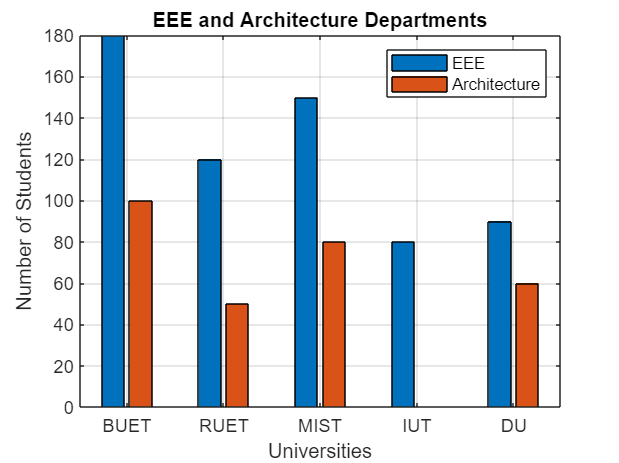


EEE_values = University_BD{"EEE",:};
Arch_values = University_BD{"Architecture",:};

figure;
bar([EEE_values; Arch_values]')
xticklabels(University_BD.Properties.VariableNames)
legend({'EEE','Architecture'})
xlabel('Universities')
ylabel('Number of Students')
title('EEE and Architecture Departments')
grid on;

**Exercise - 05**

cities = readtable('worldcities.csv');
uniqueCountries = unique(cities.country);
numUniqueCountries = numel(uniqueCountries);


[~, idxFirst] = unique(cities.country, 'stable');
duplicateCountries = cities.country;
duplicateCountries(idxFirst) = [];  % Only duplicates left

disp(['Number of unique countries: ', num2str(numUniqueCountries)])

Number of unique countries: 223


if isempty(duplicateCountries)
    disp('No duplicate country entries.')
else
    disp('Duplicate country entries exist.')
end

Duplicate country entries exist.



highPopCities = cities(cities.population > 1e7, :);
disp(['Number of cities with population > 10 million: ', num2str(height(highPopCities))])

Number of cities with population > 10 million: 39



popOver5M = cities(cities.population > 5e6, :);
disp("Cities with population > 5 million:")

Cities with population > 5 million:


disp(popOver5M)

            city                 city_ascii           lat        lng            country            iso2      iso3                   admin_name                   capital      population        id    
    ____________________    ____________________    _______    _______    ____________________    ______    _______    ____________________________________    ___________    __________    __________

    {'Tokyo'           }    {'Tokyo'           }      35.69     139.69    {'Japan'           }    {'JP'}    {'JPN'}    {'Tōkyō'                           }    {'primary'}    3.7977e+07    1.3927e+09
    {'Jakarta'         }    


primaryCapitals = cities(strcmpi(cities.capital, 'primary'), :);
disp("Primary capital cities:")

Primary capital cities:


disp(primaryCapitals)

                city                          city_ascii                lat        lng                    country                    iso2      iso3                     admin_name                      capital      population        id    
    _____________________________    _____________________________    _______    _______    ____________________________________    ______    _______    _________________________________________    ___________    __________    __________

    {'Tokyo'                    }    {'Tokyo'                    }      35.69     139.69    {'Japan'                           }    {'JP'}    {'JPN'}

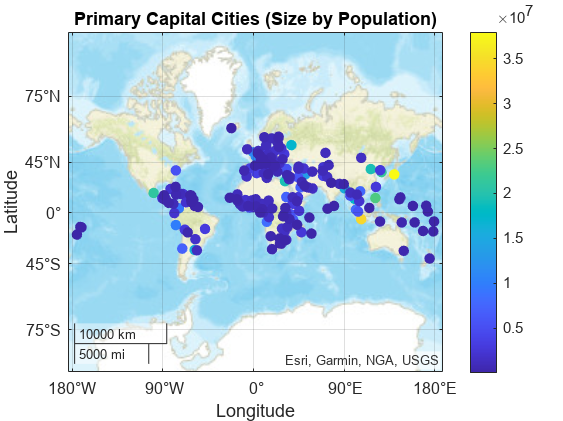


figure;
geoscatter(primaryCapitals.lat, primaryCapitals.lng, ...
    40, primaryCapitals.population, 'filled')
geobasemap streets
title('Primary Capital Cities (Size by Population)')
colorbar

selectedCountries = cities(ismember(cities.country, {'Bangladesh', 'United States'}), :);
disp("Cities in Bangladesh and the United States:");

Cities in Bangladesh and the United States:


disp(selectedCountries)

                   city                               city_ascii                 lat        lng           country          iso2      iso3             admin_name             capital      population        id    
    __________________________________    __________________________________    ______    _______    _________________    ______    _______    ________________________    ___________    __________    __________

    {'New York'                      }    {'New York'                      }    40.694    -73.925    {'United States'}    {'US'}    {'USA'}    {'New York'            }    {0×0 char }    1.8713e+07      1

rowNames = matlab.lang.makeUniqueStrings(primaryCapitals.country);
capitalTable = table(primaryCapitals.city, primaryCapitals.population, ...
    'VariableNames', {'City', 'Population'}, ...
    'RowNames', rowNames)

capitalTable = 208×2 table
                              City          Population
                        ________________    __________

    Japan               {'Tokyo'       }    3.7977e+07
    Indonesia           {'Jakarta'     }     3.454e+07
    Philippines         {'Manila'      }    2.3088e+07
    Korea, South        {'Seoul'       }    2.1794e+07
    Mexico              {'Mexico City' }    2.0996e+07
    China               {'Beijing'     }    1.9433e+07
    Egypt               {'Cairo'       }    1.9372e+07
    Russia              {'Moscow'      }    1.7125e+07
    Thailand            {'Bangkok'     }    1.7066e+07
    Argentina           {'Buenos Aires'}    1.6157e+07
    Bangladesh          {'Dhaka'       }    1.5443e+07
  

**Exercise - 06**

dataTbl=readtable("BigML_Dataset.csv");

%% Task i - Count missing entries
null_count = sum(ismissing(dataTbl));
total_missing = sum(null_count)

total_missing = 0

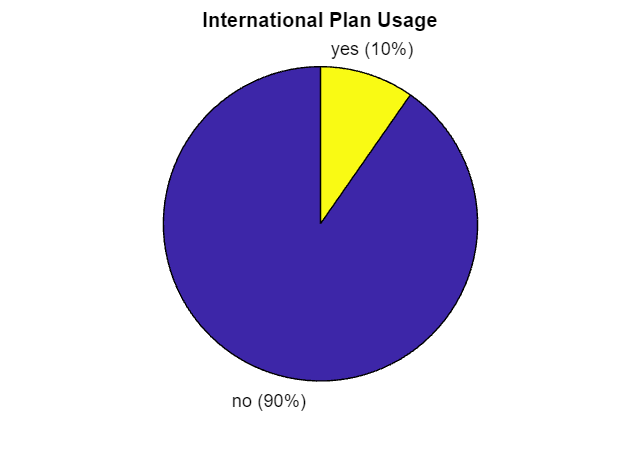


%% Task ii - Pie charts for 'internationalPlan' and 'churn'
figure;
ipCats = categorical(dataTbl.internationalPlan);
pie(ipCats)
title("International Plan Usage")

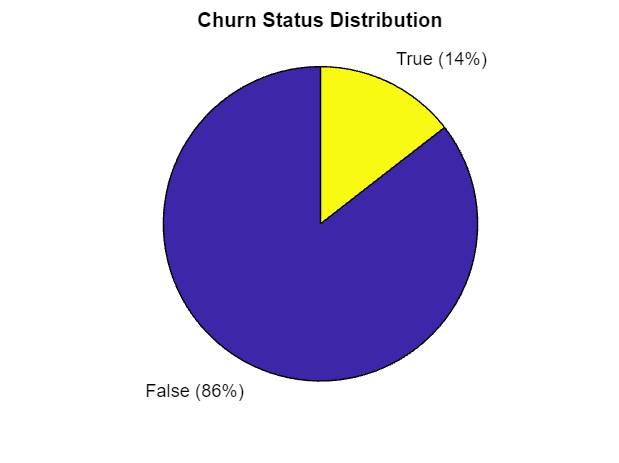


figure;
churnCats = categorical(dataTbl.churn);
pie(churnCats)
title("Churn Status Distribution")

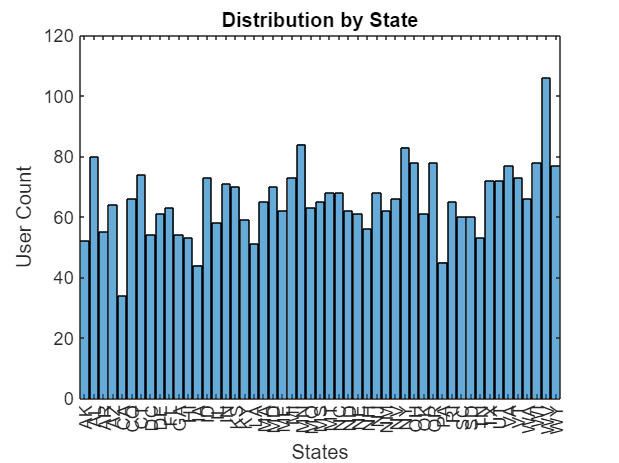


%% Task iii - Histogram for States
figure;
histogram(categorical(dataTbl.state))
xlabel('States')
ylabel('User Count')
title('Distribution by State')


%% Task iv - State with most users
[stateLabels, ~, idxStates] = unique(dataTbl.state);
userCountPerState = accumarray(idxStates, 1);
[~, iMax] = max(userCountPerState);
topState = stateLabels{iMax}

topState = 'WV'


%% Task v - State with most churned users
churnRows = strcmpi(dataTbl.churn, "True");
churnStates = dataTbl.state(churnRows);
[churnFreq, churnStateList] = groupcounts(churnStates);
[~, churnMaxIdx] = max(churnFreq);
mostChurnedState = churnStateList(churnMaxIdx)

mostChurnedState = 1×1 cell array
    {'NJ'}



%% Task vi - Users with more than one customer service call
svcQuery = dataTbl.customerServiceCalls > 1;
nHeavyServiceUsers = sum(svcQuery)

nHeavyServiceUsers = 1455


%% Task vii - Add new column 'totalCharge'
dataTbl.totalCharge = dataTbl.totalDayCharge + ...
                      dataTbl.totalEveCharge + ...
                      dataTbl.totalNightCharge + ...
                      dataTbl.totalIntlCharge

dataTbl = 3333×22 table
    state     accountLength    areaCode    phoneNumber     internationalPlan    voiceMailPlan    numberVmailMessages    totalDayMinutes    totalDayCalls    totalDayCharge    totalEveMinutes    totalEveCalls    totalEveCharge    totalNightMinutes    totalNightCalls    totalNightCharge    totalIntlMinutes    totalIntlCalls    totalIntlCharge    customerServiceCalls      churn      totalCharge
    ______    _____________    ________    ____________    _________________    _____________    _



%% Task viii - Average charge per state
[stateGroups, stateList] = findgroups(dataTbl.state);
meanCharges = splitapply(@mean, dataTbl.totalCharge, stateGroups);
averageChargesByState = table(stateList, meanCharges, ...
    'VariableNames', {'State', 'AverageCharge'})

averageChargesByState = 51×2 table
    State     AverageCharge
    ______    _____________

    {'AK'}        57.35    
    {'AL'}       59.443    
    {'AR'}       59.076    
    {'AZ'}       56.733    
    {'CA'}       59.718    
    {'CO'}       59.178    
    {'CT'}       59.084    
    {'DC'}        57.97    
    {'DE'}       59.335    
    {'FL'}       59.935    
    {'GA'}       60.301    
    {'HI'}       58.059    
    {'IA'}        58.97    
    {'ID'}        58.86    
    {'IL'}       57.923    
    {'IN'}       62.788    



%% Task ix - Reimport with proper phone number format
opts = detectImportOptions('BigML_Dataset.csv');
opts = setvartype(opts, 'phoneNumber', 'string');
dataTbl = readtable('BigML_Dataset.csv', opts);


%% Task x - Clean phone number format
dataTbl.phoneNumber = regexprep(dataTbl.phoneNumber, '-', '');




function res = amicable_pair(n1,n2)    %% exc 1
factors1 = n1 ./ (2:n1); 
factors2 = n2 ./ (2:n2);

sum1 = sum(unique(factors1(mod(n1, factors1) == 0 & mod(factors1,1)==0)));
sum2 = sum(unique(factors2(mod(n2, factors2) == 0 & mod(factors2,1)==0)));

res = (sum1 == n2 & sum2 == n1);
end

%% exc 2

function prime_set= goldbach_marginal(n)

if n <= 5 
    error("Numbers below or equal to 5 don't satisfy the conjecture.");
else


prime_set = [];
primes_list = primes(n);
len = length(primes_list);

for i = 1:len
    for j = i:len
        for k = j:len
            if primes_list(i) + primes_list(j) + primes_list(k) == n
                prime_set(end+1,:) = [primes_list(i), primes_list(j), primes_list(k)];
            end
        end
    end
end

end
end

%% exc 3

function result = lunar_add(aa, bb, ops)

% Default operation
if nargin < 3
    ops = 'Addition';
end

cc = num2str(aa) - '0';
dd = num2str(bb) - '0';

len1 = length(cc);
len2 = length(dd);
maxlen = max(len1, len2);

cc = [zeros(1, maxlen - len1), cc];
dd = [zeros(1, maxlen - len2), dd];

ee = zeros(1, maxlen);


if strcmpi(ops,'Addition')
    for i = 1:maxlen
        ee(i) = max(cc(i), dd(i));
    end

elseif strcmpi(ops,'Multiplication')
    disp("unsloved");
end


result = str2double(sprintf('%d', ee));
end